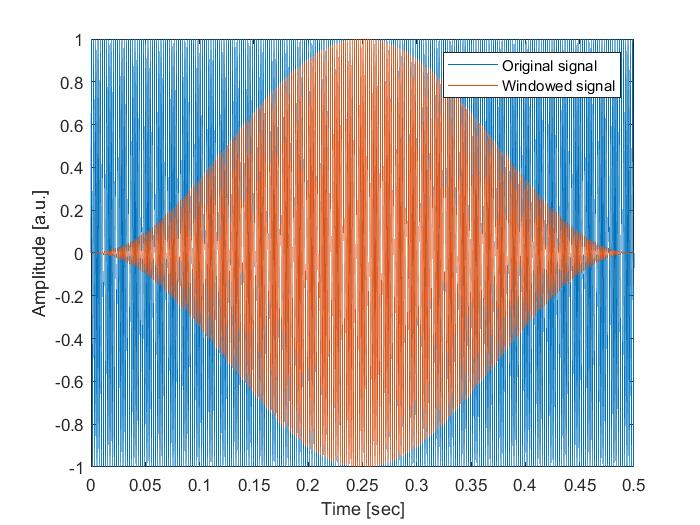

fs = 44100; T = 1; Tburst = T/2; t = 0:1/fs:T-1/fs;
sig = [sin(2*pi*500*t(1:Tburst*fs))'; zeros((T-Tburst)*fs,1)];
w = hann(Tburst*fs);
sig_w = [w.*sin(2*pi*500*t(1:Tburst*fs))'; zeros((T-Tburst)*fs,1)];
figure("Name", "Windowing")
plot(linspace(0,1,fs*T), sig), hold on; 
plot(linspace(0,1,fs*T), sig_w), hold off
xlim([0 Tburst])
xlabel("Time [sec]")
ylabel("Amplitude [a.u.]")
legend(["Original signal", "Windowed signal"])